#                 Antenna Array Processing

##                                            HW10-S3

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1402/03/21       

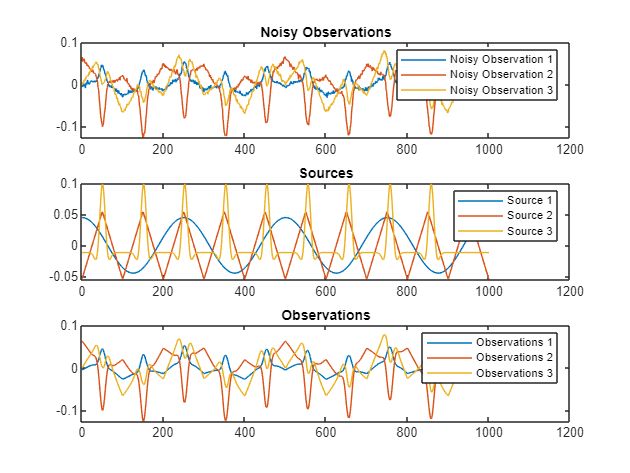

clear; clc; close all;
% Load Data:
Data  = load("hw10.mat");
A     = Data.A;     S = Data.S;  Noise = Data.Noise;
X     = A*S+Noise;  X_Noiseless = A*S;
% Depict X:
figure()
subplot(3,1,1)
plot(X(1,:)); hold on; plot(X(2,:)); plot(X(3,:)); hold off;
title("Noisy Observations")
legend("Noisy Observation 1","Noisy Observation 2","Noisy Observation 3")
subplot(3,1,2)
plot(S(1,:)); hold on; plot(S(2,:)); plot(S(3,:)); hold off;
title("Sources")
legend("Source 1","Source 2","Source 3")

subplot(3,1,3)
plot(X_Noiseless(1,:)); hold on; plot(X_Noiseless(2,:)); plot(X_Noiseless(3,:)); hold off;
title("Observations")
legend("Observations 1","Observations 2","Observations 3")

% WHitening theData:
[U , Gamma] = eig(X*X');
W = Gamma^(-0.5);
Z = W*U'*X; % Whitened Data

R_z = Z*Z';
disp(R_z); % We can see that Rz equals to I where all elements are zero excepts those 1s on the dig.

    1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000



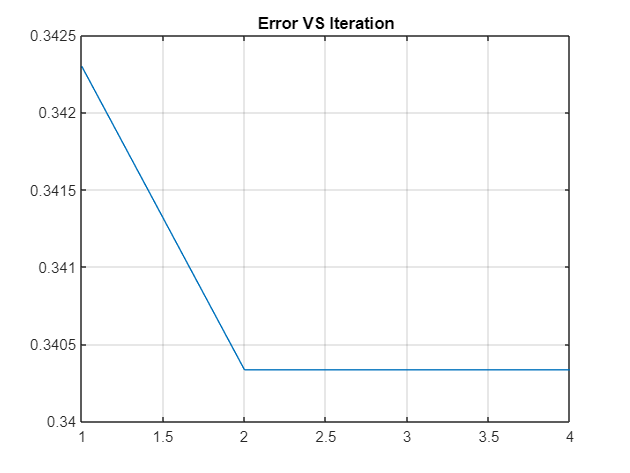


B = generate_orthonormal_matrix(size(A,1))  ; % Because B and A are in the same size due to the fact that we have M=N!



mu       = 1e-02;
Max_Iter = 2e+3;
thresh_cntr = 1e-1;
thresh_B = 1e-10;

Error_Iter_deflate = zeros(1,Max_Iter)+inf;
cntr = 1;

y_hat = B*Z;
MIN_ERR = inf;

Utility = zeros(3,1);
while(true)
    B_prev = B;
    
    % Update B:
    for i=1:length(B) % Each Row
         
         % Update Based on GP Method
         Part_1_of_Stepsize = F1_Mine(B(i,:)*Z);
         Part_2_of_Stepsize = mean( Z*( (B(i,:)*Z)*exp(-(B(i,:)*Z).^2/2)' )/length(Z) ,2 );
         StepSize      =  Part_1_of_Stepsize*Part_2_of_Stepsize ; 
         B(i,:)        =  B(i,:) + mu*StepSize'  ;
         B(i,:)        =  B(i,:)/norm(B(i,:));   % Normalization
         B(i,:)        =  ( eye(size(B)) - B(1:i-1,:)'*B(1:i-1,:)   )* B(i,:)';  % Orthogonality
         
         
    end
    
    [Error_Perm,y_Hat_Chosen,B] = Perm_AMP_Disamb(B,S,Z);
    Error_Iter_deflate(cntr)     = min(Error_Perm);  
    y_hat = B*Z;
    New_Utility = [F1_Mine(y_hat(1,:)); F1_Mine(y_hat(2,:)) ; F1_Mine(y_hat(2,:)) ];
    Utility     = [Utility, New_Utility]; 
    % Check Convergence:
    if( (abs(Error_Iter_deflate(1,cntr))<thresh_cntr) || (cntr>Max_Iter) || ( norm(B_prev - B,'fro')<thresh_B  ) )
        break;
    end
    if ( Error_Iter_deflate(cntr)<MIN_ERR  )
        y_hat_best = y_Hat_Chosen;
        B_hat_best = B;
        Index_Best = cntr;
        MIN_ERR = Error_Iter_deflate(cntr);
    end
    cntr = cntr +1;

end


figure()
plot(Error_Iter_deflate)
grid on
title("Error VS Iteration")


disp("calculated Error Equals to: "+min(Error_Iter_deflate))

calculated Error Equals to: 0.34033


disp(abs(B_hat_best*W*U'*A))

    0.9714    0.1712    0.1659
    0.1536    1.1226    0.3739
    0.1198    0.2130    1.0657



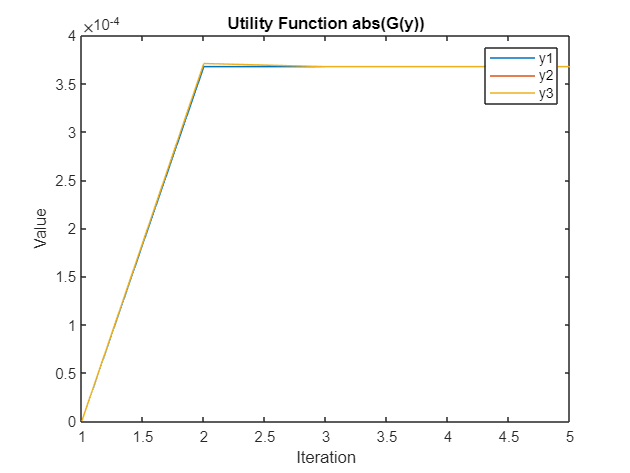

figure()
plot(Utility')
title("Utility Function abs(G(y))")
xlabel("Iteration")
ylabel("Value")
legend("y1","y2","y3")

## Signal Illustration:

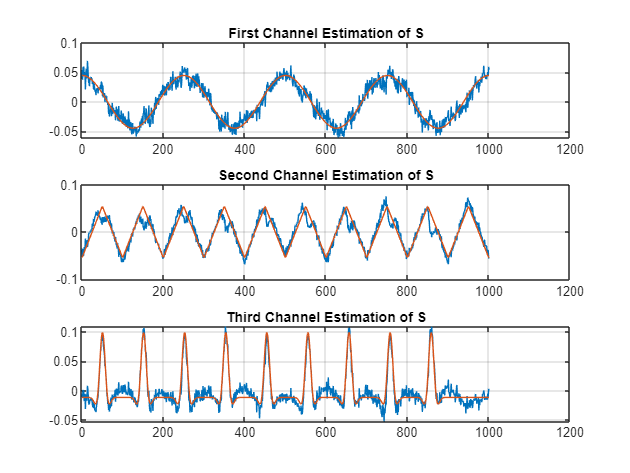

% Recovered S_hat:
y = y_Hat_Chosen;


figure()
subplot(3,1,1)
plot(y(1,:))% Permutaion
hold on
plot(S(1,:))
hold off
grid on
title("First Channel Estimation of S")


subplot(3,1,2)
plot(y(2,:))
hold on
plot(S(2,:))
hold off
grid on
title("Second Channel Estimation of S")


subplot(3,1,3)
plot(y(3,:))
hold on
plot(S(3,:))
hold off
grid on
title("Third Channel Estimation of S")

## Functions:

function matrix = generate_orthonormal_matrix(size)
    % Step 1: Generate a random matrix
    matrix = randn(size, size);
    
    % Step 2: Apply the Gram-Schmidt process
    for i = 1:size
        for j = 1:i-1
            matrix(:, i) = matrix(:, i) - dot(matrix(:, j), matrix(:, i)) * matrix(:, j);
        end
    end
    
    % Step 3: Normalize each column
    norms = vecnorm(matrix);
    matrix = matrix ./ norms;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [Error_Perm,S_Hat_Chosen,B]  = Perm_AMP_Disamb(B,S,Z) %% Perm_AMP_Disamb
    
        Final_Result_S_hat = calculate_permutations_and_Signs(B);
        % Calc the Error:
        L3 = size(Final_Result_S_hat,3);
        Error_Perm = zeros(1,L3);
        for i=1:L3
            S_hat_temp =  Final_Result_S_hat(:,:,i)*Z;
            Error_Perm(1,i) = norm(S_hat_temp-S,"fro")/norm(S,"fro"); 
        end
        [~ , idx ] = min(Error_Perm);
        S_Hat_Chosen = Final_Result_S_hat(:,:,idx)*Z;
        B = Final_Result_S_hat(:,:,idx);
    end
    
    function    Final_Result = calculate_permutations_and_Signs(matrix)    
        num_of_columns_matrix = size(matrix,2);
        variations = calculate_variations(matrix);
        cntr =1;
        %Temp = zeros(size(variations(:,:,1)));
        Final_Result = zeros([size(matrix),  (2^num_of_columns_matrix)*factorial(num_of_columns_matrix) ]);
        for j=1:size(variations,3)
            Temp = variations(:,:,j);
    
             num_of_columns = size(Temp,2);
             Different_Col_Arranges = perms(1:num_of_columns);
            for i=1:size(Different_Col_Arranges,1)
                Final_Result(:,:,cntr) =  Temp(:,Different_Col_Arranges(i,:))  ;
                cntr = cntr +1; 
            end
        end
    
    
    end
    
    
    function variations = calculate_variations(matrix)
        % Get the size of the matrix
        [num_rows, num_cols] = size(matrix);
        
        % Generate all possible combinations of signs
        sign_combinations = cell(1, num_rows);
        [sign_combinations{:}] = ndgrid([-1, 1]);
        sign_combinations = cellfun(@(x) x(:), sign_combinations, 'UniformOutput', false);
        sign_combinations = cat(2, sign_combinations{:});
        
        % Calculate the number of variations
        num_variations = size(sign_combinations, 1);
        
        % Initialize the variations array
        variations = zeros(num_rows, num_cols, num_variations);
        
        % Generate the variations
        for i = 1:num_variations
            % Apply the sign variations to each row
            variations( :, :, i) = matrix .* reshape(sign_combinations(i, :), 1, num_rows, 1);
        end
    end
    
    function value = F1_Mine(y)
        NU = randn(size(y));

        value     =  ( (-exp(-y*y'/2))  -exp(-NU*NU'/2) ).^2/length(y) ;
    end